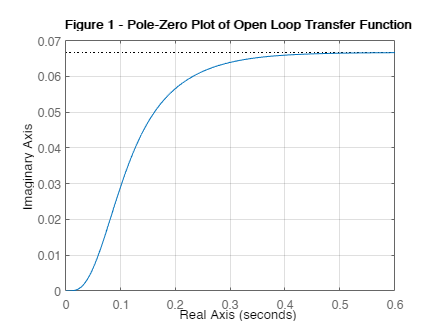

% syms s t;
s = tf('s');
hold off 


student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

zeros_natural = (s+(2*sn_B));
poles_natural = (s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*(s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C);
sys_natural = zeros_natural/poles_natural

sys_natural =
 
                              s + 36
  --------------------------------------------------------------
  s^5 + 164 s^4 + 11467 s^3 + 421938 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.



adjusted_k = dcgain(sys_natural);

zeros = (s+(2*sn_B));
complex_poles = (s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C)

complex_poles =
 
  s^2 + 66 s + 2178
 
Continuous-time transfer function.



poles = adjusted_k*sn_F*(s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*complex_poles;

oltf = minreal(zeros/poles)

oltf =
 
                         8.998e04 s + 3.239e06
  -------------------------------------------------------------------
  s^5 + 164 s^4 + 1.147e04 s^3 + 4.219e05 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.




CF = 3*sn_C/2;

H = 2*CF/(s+2*CF);

G = oltf/H; 

% these should be equal!
k = dcgain(oltf)

k = 0.0667

ref = 1/sn_F % value it should be

ref = 0.0667

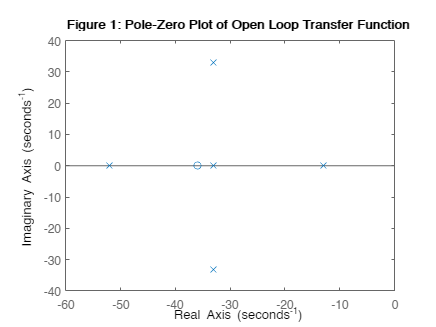


% TF = KG/(1+KGH)
% KGH = KG/TF-1

[num_ol, den_ol] = tfdata(oltf,'v');

%%%%%%%%%%%
% open loop
C1_GH = oltf;
%%%%%%%%%%

figure()
pzmap(C1_GH);
title("Figure 1: Pole-Zero Plot of Open Loop Transfer Function")

% Calc 2
%%%%%%%%%%%%%%
C2_Ku = margin(oltf)

C2_Ku = 68.4818

%%%%%%%%%%%%%%

% Calc 3 - CL TF
Kp = C2_Ku/2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
C3_T = Kp*G/(1+Kp*G*H); % closed looped tf 

C3_Ess = dcgain(1/(1+Kp*oltf))*100

C3_Ess = 30.4625

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%
pzmap(minreal(C3_oltf))

Unrecognized function or variable 'C3_oltf'.






%%%%%%%%%%%%%%%%%%%%%

% Calc 4 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
C4_Kp = margin(oltf/s);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

H_new = 2*CF/(s+2*CF);
G_new = oltf/(s*H_new); 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
C4_T = (C4_Kp/2)*G_new/(1+(C4_Kp/2)*G_new*H_new);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

temp = C4_Kp/2

temp = 166.5643

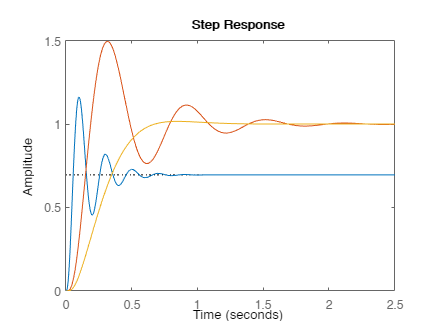

%%%% FIG 2 %%%
hold off

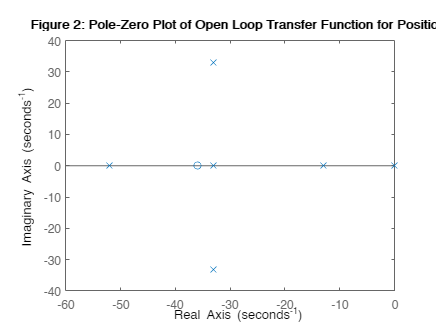

pzmap(oltf/s);
title("Figure 2: Pole-Zero Plot of Open Loop Transfer Function for Position")
hold off

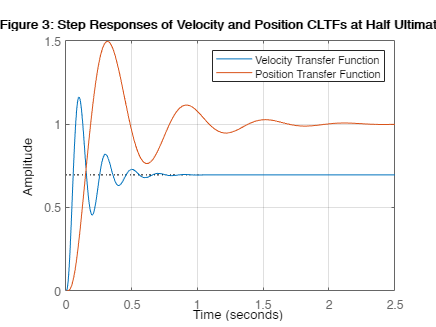


%%%% FIG 3 %%%%
figure();
step(C3_T)
hold on 
step(C4_T)
title("Figure 3: Step Responses of Velocity and Position CLTFs at Half Ultimate Gain")
legend("Velocity Transfer Function", "Position Transfer Function")
grid on
hold off

% Calc 5

% <2% overshoot = doesn't go over 1.02
maximum = 999;
inc = 1;
Kp_loop = C4_Kp;

while maximum > 1.02
    H_loop = 2*CF/(s+2*CF);
    G_loop = oltf/(s*H_new); 
    [y_loop, t_loop] = step(Kp_loop*G_loop/(1+Kp_loop*G_loop*H_loop));

    if max(y_loop) < maximum
        maximum = max(y_loop);
    end

    Kp_loop = Kp_loop - inc;
end

C5_K = Kp_loop

C5_K = 49.1285

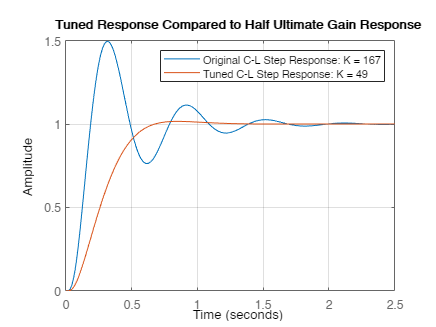

hold off

figure(4);
step(C4_T)
hold on
grid on
step(Kp_loop*G_loop/(1+Kp_loop*G_loop*H_loop))
title("Tuned Response Compared to Half Ultimate Gain Response")
legend("Original C-L Step Response: K = 167", "Tuned C-L Step Response: K = 49")
hold off